%% 2D CPU/GPU Die Cooling Simulation: Explicit & Implicit Transients + Steady State
% Models a chip package cross-section undergoing transient thermal analysis.
%
% Geometry (z = 0 is bottom of silicon die, z = Lz is top of heatspreader):
%   Layer 1 (bottom): Silicon die         with localized heat sources (CPU cores)
%   Layer 2 (middle): TIM                 thermal interface material
%   Layer 3 (top):    Copper heatspreader convection to forced air on top surface
%
% Boundary Conditions:
%   Top surface    (z = Lz): Convection to forced air, h = 2000 W/m^2-K, T_inf = 300 K
%   Left surface   (x = 0):  Convection to air, same h and T_inf
%   Right surface  (x = Lx): Convection to air, same h and T_inf
%   Bottom surface (z = 0):  Adiabatic (insulated PCB side)
%
% Solvers:
%   1. Transient Explicit  (forward-time, central-space, Table 5.3)
%   2. Transient Implicit  (backward-time, central-space, Gauss-Seidel per step)
%   3. Steady State        (Table 4.2 stencils, Gauss-Seidel)
%
% Outputs:
%   - 8 transient snapshots (explicit)
%   - MP4 animation: cpu_cooling_explicit.mp4
%   - Final 3-panel comparison: explicit | steady-state | implicit
%   - Cooldown phase: cores off, chip returns to ambient
%   - MP4 animation: cpu_cooldown_explicit.mp4
%   - Peak temperature vs time plot

clear; clc; close all;

%% =========================================================================
%  GEOMETRY AND GRID
% =========================================================================
Lx = 0.020;   % m, die width  (20 mm)
Lz = 0.006;   % m, total stack height (6 mm)

t_die = 0.003;   % m, silicon die (3 mm)
t_tim = 0.0005;  % m, TIM        (0.5 mm)
t_hs  = 0.0025;  % m, Cu spreader (2.5 mm)

nodes_per_meter = 500;
Nx = round(Lx * nodes_per_meter) + 1;
Nz = round(Lz * nodes_per_meter) + 1;
dx = Lx / (Nx - 1);
dz = Lz / (Nz - 1);

if abs(dx - dz) > 1e-7
    error('Non-square grid: dx=%.4g, dz=%.4g.', dx, dz);
end

x = linspace(0, Lx, Nx);
z = linspace(0, Lz, Nz);
fprintf('Grid: %d x %d nodes | dx = dz = %.4g m\n', Nx, Nz, dx);

Grid: 11 x 4 nodes | dx = dz = 0.002 m



%% =========================================================================
%  MATERIAL PROPERTIES
% =========================================================================
k_si = 130;  rho_si = 2330; cp_si = 700;
k_tim_v = 5.0; rho_tim = 2500; cp_tim = 800;
k_cu = 400;  rho_cu = 8960; cp_cu = 385;

K   = zeros(Nz, Nx);
RHO = zeros(Nz, Nx);
CP  = zeros(Nz, Nx);

for i = 1:Nz
    if z(i) <= t_die
        K(i,:) = k_si;  RHO(i,:) = rho_si;  CP(i,:) = cp_si;
    elseif z(i) <= t_die + t_tim
        K(i,:) = k_tim_v; RHO(i,:) = rho_tim; CP(i,:) = cp_tim;
    else
        K(i,:) = k_cu;  RHO(i,:) = rho_cu;  CP(i,:) = cp_cu;
    end
end

ALPHA = K ./ (RHO .* CP);

%% =========================================================================
%  HEAT SOURCE MAP  (3 CPU cores in bottom of silicon die)
% =========================================================================
Q = zeros(Nz, Nx);
q_core = 5e8;
core_h = t_die * 0.4;
core_w = Lx * 0.12;
core_x_centers = [Lx*0.20, Lx*0.50, Lx*0.80];

[Xg, Zg] = meshgrid(x, z);
for cidx = 1:3
    cx = core_x_centers(cidx);
    Q( Zg <= core_h & abs(Xg - cx) <= core_w/2 ) = q_core;
end

%% =========================================================================
%  BOUNDARY CONDITIONS & TIME STEP
% =========================================================================
T_init = 300;
T_inf  = 300;
h_conv = 2000;

k_min_global = min(K(:));
Bi_global    = h_conv * dx / k_min_global;
alpha_max    = max(ALPHA(:));

Fo_lim = min([1/4, 1/(2*(2+Bi_global)), 1/(4*(1+Bi_global))]);
Fo     = 0.45 * Fo_lim;
dt     = Fo * dx^2 / alpha_max;

fprintf('Fo = %.4g (lim %.4g) | dt = %.4g s | Bi = %.4g\n', Fo, Fo_lim, dt, Bi_global);

Fo = 0.1091 (lim 0.2425) | dt = 0.003765 s | Bi = 0.03077



FO = ALPHA * dt / dx^2;
BI = h_conv * dx ./ K;
QS = Q .* dx^2 ./ K;

%% =========================================================================
%  TRANSIENT EXPLICIT SOLVER  (fully vectorized)
% =========================================================================
T = T_init * ones(Nz, Nx);

tol_abs    = 1e-3;
hold_steps = 10;
max_steps  = 3e6;
pass_ct    = 0;

t_char     = (min(Lx,Lz))^2 / alpha_max;
snap_times = t_char * [1e-4 5e-4 2e-3 8e-3 2e-2 6e-2 1.5e-1];
snap_k = 1; num_snaps = 8; time = 0;

figSnaps = figure('Name','CPU Die Cooling - Explicit Snapshots','Color','w');
colormap('hot');

videoName   = 'cpu_cooling_explicit.mp4';
frame_dt    = max(dt, t_char / 400);
nextFrame_t = 0;
vw = VideoWriter(videoName, 'MPEG-4');
vw.FrameRate = 30;
open(vw);

figAnim = figure('Visible','off','Color','w','Position',[100 100 640 400]);
axA  = axes('Parent', figAnim);
hImg = imagesc(axA, x*1e3, z*1e3, T);
set(axA, 'YDir','normal');
colormap(axA,'hot');
cb = colorbar(axA); ylabel(cb,'Temperature (K)');
xlabel(axA,'x (mm)'); ylabel(axA,'z (mm)');
title(axA, sprintf('t = %.4g s', time)); axis(axA,'tight');
hold(axA,'on');
yline(axA, t_die*1e3,         'c--','LineWidth',1.2);
yline(axA, (t_die+t_tim)*1e3, 'b--','LineWidth',1.2);
hold(axA,'off');
drawnow('expose');
writeVideo(vw, getframe(figAnim));
nextFrame_t = frame_dt;

fprintf('\nRunning explicit solver (vectorized)...\n');


Running explicit solver (vectorized)...



for step = 1:max_steps

    Tp = T;

    % Interior nodes (Case 1)
    fo = FO(2:Nz-1, 2:Nx-1);
    qs = QS(2:Nz-1, 2:Nx-1);
    Tp(2:Nz-1, 2:Nx-1) = fo.*(T(3:Nz,2:Nx-1) + T(1:Nz-2,2:Nx-1) + ...
                               T(2:Nz-1,3:Nx) + T(2:Nz-1,1:Nx-2)) ...
                        + (1 - 4*fo).*T(2:Nz-1,2:Nx-1) + fo.*qs;

    % Top edge (Case 3)
    i = Nz;
    fo_t = FO(i,2:Nx-1); bi_t = BI(i,2:Nx-1); qs_t = QS(i,2:Nx-1);
    Tp(i,2:Nx-1) = fo_t.*(2*T(i-1,2:Nx-1) + T(i,3:Nx) + T(i,1:Nx-2) + 2*bi_t*T_inf) ...
                 + (1 - 4*fo_t - 2*bi_t.*fo_t).*T(i,2:Nx-1) + fo_t.*qs_t;

    % Bottom edge (adiabatic ghost node)
    i = 1;
    fo_b = FO(i,2:Nx-1); qs_b = QS(i,2:Nx-1);
    Tp(i,2:Nx-1) = fo_b.*(2*T(i+1,2:Nx-1) + T(i,3:Nx) + T(i,1:Nx-2)) ...
                 + (1 - 4*fo_b).*T(i,2:Nx-1) + fo_b.*qs_b;

    % Left edge (Case 3)
    j = 1;
    fo_l = FO(2:Nz-1,j); bi_l = BI(2:Nz-1,j); qs_l = QS(2:Nz-1,j);
    Tp(2:Nz-1,j) = fo_l.*(2*T(2:Nz-1,j+1) + T(3:Nz,j) + T(1:Nz-2,j) + 2*bi_l*T_inf) ...
                 + (1 - 4*fo_l - 2*bi_l.*fo_l).*T(2:Nz-1,j) + fo_l.*qs_l;

    % Right edge (Case 3)
    j = Nx;
    fo_r = FO(2:Nz-1,j); bi_r = BI(2:Nz-1,j); qs_r = QS(2:Nz-1,j);
    Tp(2:Nz-1,j) = fo_r.*(2*T(2:Nz-1,j-1) + T(3:Nz,j) + T(1:Nz-2,j) + 2*bi_r*T_inf) ...
                 + (1 - 4*fo_r - 2*bi_r.*fo_r).*T(2:Nz-1,j) + fo_r.*qs_r;

    % Corners (Case 4)
    i=Nz; j=1;   fo_c=FO(i,j); bi_c=BI(i,j); qs_c=QS(i,j);
    Tp(i,j) = 2*fo_c*(T(i-1,j)+T(i,j+1)+2*bi_c*T_inf) + (1-4*fo_c-4*bi_c*fo_c)*T(i,j) + 2*fo_c*qs_c;
    i=Nz; j=Nx;  fo_c=FO(i,j); bi_c=BI(i,j); qs_c=QS(i,j);
    Tp(i,j) = 2*fo_c*(T(i-1,j)+T(i,j-1)+2*bi_c*T_inf) + (1-4*fo_c-4*bi_c*fo_c)*T(i,j) + 2*fo_c*qs_c;
    i=1;  j=1;   fo_c=FO(i,j); bi_c=BI(i,j); qs_c=QS(i,j);
    Tp(i,j) = 2*fo_c*(T(i+1,j)+T(i,j+1)+2*bi_c*T_inf) + (1-4*fo_c-4*bi_c*fo_c)*T(i,j) + 2*fo_c*qs_c;
    i=1;  j=Nx;  fo_c=FO(i,j); bi_c=BI(i,j); qs_c=QS(i,j);
    Tp(i,j) = 2*fo_c*(T(i+1,j)+T(i,j-1)+2*bi_c*T_inf) + (1-4*fo_c-4*bi_c*fo_c)*T(i,j) + 2*fo_c*qs_c;

    dT_max = max(abs(Tp(:) - T(:)));
    T    = Tp;
    time = time + dt;

    % Animation frame
    if time >= nextFrame_t
        set(hImg, 'CData', T);
        title(axA, sprintf('t = %.4g s', time));
        drawnow('expose');
        writeVideo(vw, getframe(figAnim));
        nextFrame_t = nextFrame_t + frame_dt;
    end

    % Snapshots 1..7
    figure(figSnaps);
    while (snap_k <= num_snaps-1) && (time >= snap_times(snap_k))
        subplot(2,4,snap_k);
        imagesc(x*1e3, z*1e3, T); set(gca,'YDir','normal');
        colormap('hot'); colorbar;
        title(sprintf('t = %.3g s', time));
        xlabel('x (mm)'); ylabel('z (mm)');
        hold on;
        yline(t_die*1e3,         'c--','LineWidth',1);
        yline((t_die+t_tim)*1e3, 'b--','LineWidth',1);
        hold off;
        snap_k = snap_k + 1;
    end

    pass_ct = pass_ct + (dT_max < tol_abs);
    if dT_max >= tol_abs, pass_ct = 0; end
    if pass_ct >= hold_steps
        fprintf('Explicit converged: t = %.4f s, %d steps, dT_max = %.3g K\n', time, step, dT_max);
        break
    end
end

Explicit converged: t = 22.1379 s, 5880 steps, dT_max = 0.000993 K


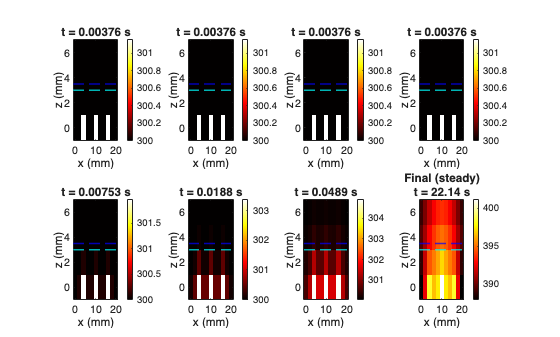


% 8th snapshot
T_jmax = max(T(:));
T_jmin = min(T(:));

figure(figSnaps);
subplot(2,4,num_snaps);
imagesc(x*1e3, z*1e3, T); set(gca,'YDir','normal');
colormap('hot'); colorbar;
title(sprintf('Final (steady)\nt = %.2f s', time));
xlabel('x (mm)'); ylabel('z (mm)');
hold on;
yline(t_die*1e3,         'c--','LineWidth',1);
yline((t_die+t_tim)*1e3, 'b--','LineWidth',1);
hold off;


set(hImg, 'CData', T);
title(axA, sprintf('Final (steady) t = %.3f s', time));
drawnow('expose'); writeVideo(vw, getframe(figAnim));
close(vw); close(figAnim);
fprintf('Saved animation: %s\n', videoName);

Saved animation: cpu_cooling_explicit.mp4



T_explicit_final = T;

%% =========================================================================
%  TRANSIENT IMPLICIT SOLVER (vectorized Gauss-Seidel per time step)
% =========================================================================
fprintf('\nRunning implicit solver (vectorized)...\n');


Running implicit solver (vectorized)...



Tn  = T_init * ones(Nz, Nx);
Tnp = Tn;
tol_inner = 1e-6;
max_inner  = 200;
time_imp   = 0;
step_imp   = 0;
pass_ct    = 0;

while step_imp < max_steps
    step_imp = step_imp + 1;
    Tnp = Tn;

    for it = 1:max_inner
        Told_all = Tnp;

        fo = FO(2:Nz-1,2:Nx-1); qs = QS(2:Nz-1,2:Nx-1);
        Tnp(2:Nz-1,2:Nx-1) = (Tn(2:Nz-1,2:Nx-1) ...
            + fo.*(Tnp(3:Nz,2:Nx-1)+Tnp(1:Nz-2,2:Nx-1)+Tnp(2:Nz-1,3:Nx)+Tnp(2:Nz-1,1:Nx-2)) ...
            + fo.*qs) ./ (1 + 4*fo);

        i = Nz;
        fo_t=FO(i,2:Nx-1); bi_t=BI(i,2:Nx-1); qs_t=QS(i,2:Nx-1);
        Tnp(i,2:Nx-1) = (Tn(i,2:Nx-1) ...
            + fo_t.*(2*Tnp(i-1,2:Nx-1)+Tnp(i,3:Nx)+Tnp(i,1:Nx-2)) ...
            + 2*bi_t.*fo_t*T_inf + fo_t.*qs_t) ./ (1 + 2*fo_t.*(2+bi_t));

        i = 1;
        fo_b=FO(i,2:Nx-1); qs_b=QS(i,2:Nx-1);
        Tnp(i,2:Nx-1) = (Tn(i,2:Nx-1) ...
            + fo_b.*(2*Tnp(i+1,2:Nx-1)+Tnp(i,3:Nx)+Tnp(i,1:Nx-2)) ...
            + fo_b.*qs_b) ./ (1 + 4*fo_b);

        j = 1;
        fo_l=FO(2:Nz-1,j); bi_l=BI(2:Nz-1,j); qs_l=QS(2:Nz-1,j);
        Tnp(2:Nz-1,j) = (Tn(2:Nz-1,j) ...
            + fo_l.*(2*Tnp(2:Nz-1,j+1)+Tnp(3:Nz,j)+Tnp(1:Nz-2,j)) ...
            + 2*bi_l.*fo_l*T_inf + fo_l.*qs_l) ./ (1 + 2*fo_l.*(2+bi_l));

        j = Nx;
        fo_r=FO(2:Nz-1,j); bi_r=BI(2:Nz-1,j); qs_r=QS(2:Nz-1,j);
        Tnp(2:Nz-1,j) = (Tn(2:Nz-1,j) ...
            + fo_r.*(2*Tnp(2:Nz-1,j-1)+Tnp(3:Nz,j)+Tnp(1:Nz-2,j)) ...
            + 2*bi_r.*fo_r*T_inf + fo_r.*qs_r) ./ (1 + 2*fo_r.*(2+bi_r));

        i=Nz; j=1;  fo_c=FO(i,j); bi_c=BI(i,j); qs_c=QS(i,j);
        Tnp(i,j)=(Tn(i,j)+2*fo_c*(Tnp(i-1,j)+Tnp(i,j+1))+4*bi_c*fo_c*T_inf+2*fo_c*qs_c)/(1+4*fo_c*(1+bi_c));
        i=Nz; j=Nx; fo_c=FO(i,j); bi_c=BI(i,j); qs_c=QS(i,j);
        Tnp(i,j)=(Tn(i,j)+2*fo_c*(Tnp(i-1,j)+Tnp(i,j-1))+4*bi_c*fo_c*T_inf+2*fo_c*qs_c)/(1+4*fo_c*(1+bi_c));
        i=1;  j=1;  fo_c=FO(i,j); bi_c=BI(i,j); qs_c=QS(i,j);
        Tnp(i,j)=(Tn(i,j)+2*fo_c*(Tnp(i+1,j)+Tnp(i,j+1))+4*bi_c*fo_c*T_inf+2*fo_c*qs_c)/(1+4*fo_c*(1+bi_c));
        i=1;  j=Nx; fo_c=FO(i,j); bi_c=BI(i,j); qs_c=QS(i,j);
        Tnp(i,j)=(Tn(i,j)+2*fo_c*(Tnp(i+1,j)+Tnp(i,j-1))+4*bi_c*fo_c*T_inf+2*fo_c*qs_c)/(1+4*fo_c*(1+bi_c));

        if max(abs(Tnp(:)-Told_all(:))) < tol_inner, break; end
    end

    dT_max   = max(abs(Tnp(:)-Tn(:)));
    Tn       = Tnp;
    time_imp = time_imp + dt;

    pass_ct = pass_ct + (dT_max < tol_abs);
    if dT_max >= tol_abs, pass_ct = 0; end
    if pass_ct >= hold_steps
        fprintf('Implicit converged: t = %.4f s, %d steps, dT_max = %.3g K\n', time_imp, step_imp, dT_max);
        break
    end
end

Implicit converged: t = 22.1492 s, 5883 steps, dT_max = 0.000993 K



T_implicit_final = Tn;

%% =========================================================================
%  STEADY-STATE SOLVER (Table 4.2, Gauss-Seidel)
% =========================================================================
fprintf('\nRunning steady-state solver...\n');


Running steady-state solver...



Tss = T_init * ones(Nz, Nx);
tol_ss = 1e-3; max_it_ss = 3e6;
res = Inf; it = 0;

while res > tol_ss && it < max_it_ss
    res = 0; it = it + 1;
    for i = 1:Nz
        for j = 1:Nx
            Told   = Tss(i,j);
            bi_loc = BI(i,j);
            qs_loc = QS(i,j);
            if i == 1
                if     j == 1,  Tnew=(Tss(i+1,j)+Tss(i,j+1)+2*bi_loc*T_inf+qs_loc)/(2+2*bi_loc);
                elseif j == Nx, Tnew=(Tss(i+1,j)+Tss(i,j-1)+2*bi_loc*T_inf+qs_loc)/(2+2*bi_loc);
                else,           Tnew=(2*Tss(i+1,j)+Tss(i,j+1)+Tss(i,j-1)+qs_loc)/4;
                end
            elseif i == Nz
                if     j == 1,  Tnew=(Tss(i-1,j)+Tss(i,j+1)+2*bi_loc*T_inf+qs_loc)/(2+2*bi_loc);
                elseif j == Nx, Tnew=(Tss(i-1,j)+Tss(i,j-1)+2*bi_loc*T_inf+qs_loc)/(2+2*bi_loc);
                else,           Tnew=(2*Tss(i-1,j)+Tss(i,j+1)+Tss(i,j-1)+2*bi_loc*T_inf+qs_loc)/(4+2*bi_loc);
                end
            elseif j == 1
                Tnew=(Tss(i-1,j)+Tss(i+1,j)+2*Tss(i,j+1)+2*bi_loc*T_inf+qs_loc)/(4+2*bi_loc);
            elseif j == Nx
                Tnew=(Tss(i-1,j)+Tss(i+1,j)+2*Tss(i,j-1)+2*bi_loc*T_inf+qs_loc)/(4+2*bi_loc);
            else
                Tnew=(Tss(i+1,j)+Tss(i-1,j)+Tss(i,j+1)+Tss(i,j-1)+qs_loc)/4;
            end
            Tss(i,j) = Tnew;
            res = max(res, abs(Tnew-Told));
        end
    end
end
fprintf('Steady-state converged: %d iterations, max change = %.3g K\n', it, res);

Steady-state converged: 1468 iterations, max change = 0.000997 K


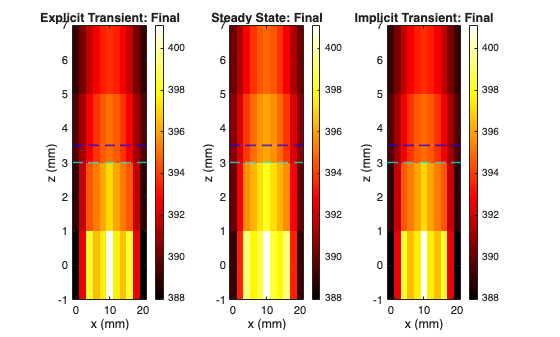


%% =========================================================================
%  FINAL COMPARISON FIGURE
% =========================================================================
T_all  = {T_explicit_final, Tss, T_implicit_final};
titles = {'Explicit Transient: Final','Steady State: Final','Implicit Transient: Final'};

figure('Name','Final Comparison','Color','w'); colormap('hot');
for p = 1:3
    subplot(1,3,p);
    imagesc(x*1e3, z*1e3, T_all{p}); set(gca,'YDir','normal');
    set(gca, 'CLim', [T_jmin, T_jmax]);
    colorbar; title(titles{p}); xlabel('x (mm)'); ylabel('z (mm)');
    hold on;
    yline(t_die*1e3,         'c--','LineWidth',1.2,'LabelHorizontalAlignment','left');
    yline((t_die+t_tim)*1e3, 'b--','LineWidth',1.2,'LabelHorizontalAlignment','left');
    hold off;
end


%% =========================================================================
%  KEY RESULTS
% =========================================================================
fprintf('\n--- Key Results ---\n');


--- Key Results ---


fprintf('Peak junction temp : %.2f K  (%.2f deg C)\n', T_jmax, T_jmax-273.15);

Peak junction temp : 401.11 K  (127.96 deg C)


fprintf('Min temperature    : %.2f K  (%.2f deg C)\n', T_jmin, T_jmin-273.15);

Min temperature    : 387.94 K  (114.79 deg C)


fprintf('Max temp rise      : %.2f K\n', T_jmax - T_init);

Max temp rise      : 101.11 K


Q_total = sum(Q(:)) * dx^2 * dx;
if Q_total > 0
    fprintf('Thermal resistance : %.4f K/W\n', (T_jmax-T_inf)/Q_total);
end

Thermal resistance : 8.4258 K/W



%% =========================================================================
%  COOLDOWN PHASE (cores off — explicit, vectorized)
% =========================================================================
fprintf('\nRunning cooldown phase (cores off)...\n');


Running cooldown phase (cores off)...



T_cd    = T_explicit_final;
pass_ct = 0;
time_cd = 0;
step_cd = 0;

t_cd_char     = t_char;
snap_times_cd = t_cd_char * [1e-3 5e-3 2e-2 8e-2 2e-1 6e-1 1.5];
snap_k_cd     = 1;

figCool = figure('Name','Cooldown Snapshots (Cores Off)','Color','w');

videoName_cd = 'cpu_cooldown_explicit.mp4';
frame_dt_cd  = max(dt, t_cd_char / 400);
nextFrame_cd = 0;
vw_cd = VideoWriter(videoName_cd, 'MPEG-4');
vw_cd.FrameRate = 30;
open(vw_cd);

figAnimCd = figure('Visible','off','Color','w','Position',[100 100 640 400]);
axC    = axes('Parent', figAnimCd);
hImgCd = imagesc(axC, x*1e3, z*1e3, T_cd);
set(axC, 'YDir','normal', 'CLim', [T_inf, T_jmax]);
colormap(axC,'hot');
cb2 = colorbar(axC); ylabel(cb2,'Temperature (K)');
xlabel(axC,'x (mm)'); ylabel(axC,'z (mm)');
title(axC,'Cooldown: t = 0 s (cores off)'); axis(axC,'tight');
hold(axC,'on');
yline(axC, t_die*1e3,         'c--','LineWidth',1.2);
yline(axC, (t_die+t_tim)*1e3, 'b--','LineWidth',1.2);
hold(axC,'off');
drawnow('expose');
writeVideo(vw_cd, getframe(figAnimCd));
nextFrame_cd = frame_dt_cd;

T_peak_history = max(T_cd(:));
T_time_history = 0;

for step_cd = 1:max_steps

    Tp = T_cd;

    fo = FO(2:Nz-1, 2:Nx-1);
    Tp(2:Nz-1, 2:Nx-1) = fo.*(T_cd(3:Nz,2:Nx-1) + T_cd(1:Nz-2,2:Nx-1) + ...
                               T_cd(2:Nz-1,3:Nx) + T_cd(2:Nz-1,1:Nx-2)) ...
                        + (1 - 4*fo).*T_cd(2:Nz-1,2:Nx-1);

    i = Nz;
    fo_t = FO(i,2:Nx-1); bi_t = BI(i,2:Nx-1);
    Tp(i,2:Nx-1) = fo_t.*(2*T_cd(i-1,2:Nx-1) + T_cd(i,3:Nx) + T_cd(i,1:Nx-2) + 2*bi_t*T_inf) ...
                 + (1 - 4*fo_t - 2*bi_t.*fo_t).*T_cd(i,2:Nx-1);

    i = 1;
    fo_b = FO(i,2:Nx-1);
    Tp(i,2:Nx-1) = fo_b.*(2*T_cd(i+1,2:Nx-1) + T_cd(i,3:Nx) + T_cd(i,1:Nx-2)) ...
                 + (1 - 4*fo_b).*T_cd(i,2:Nx-1);

    j = 1;
    fo_l = FO(2:Nz-1,j); bi_l = BI(2:Nz-1,j);
    Tp(2:Nz-1,j) = fo_l.*(2*T_cd(2:Nz-1,j+1) + T_cd(3:Nz,j) + T_cd(1:Nz-2,j) + 2*bi_l*T_inf) ...
                 + (1 - 4*fo_l - 2*bi_l.*fo_l).*T_cd(2:Nz-1,j);

    j = Nx;
    fo_r = FO(2:Nz-1,j); bi_r = BI(2:Nz-1,j);
    Tp(2:Nz-1,j) = fo_r.*(2*T_cd(2:Nz-1,j-1) + T_cd(3:Nz,j) + T_cd(1:Nz-2,j) + 2*bi_r*T_inf) ...
                 + (1 - 4*fo_r - 2*bi_r.*fo_r).*T_cd(2:Nz-1,j);

    i=Nz; j=1;  fo_c=FO(i,j); bi_c=BI(i,j);
    Tp(i,j) = 2*fo_c*(T_cd(i-1,j)+T_cd(i,j+1)+2*bi_c*T_inf) + (1-4*fo_c-4*bi_c*fo_c)*T_cd(i,j);
    i=Nz; j=Nx; fo_c=FO(i,j); bi_c=BI(i,j);
    Tp(i,j) = 2*fo_c*(T_cd(i-1,j)+T_cd(i,j-1)+2*bi_c*T_inf) + (1-4*fo_c-4*bi_c*fo_c)*T_cd(i,j);
    i=1;  j=1;  fo_c=FO(i,j); bi_c=BI(i,j);
    Tp(i,j) = 2*fo_c*(T_cd(i+1,j)+T_cd(i,j+1)+2*bi_c*T_inf) + (1-4*fo_c-4*bi_c*fo_c)*T_cd(i,j);
    i=1;  j=Nx; fo_c=FO(i,j); bi_c=BI(i,j);
    Tp(i,j) = 2*fo_c*(T_cd(i+1,j)+T_cd(i,j-1)+2*bi_c*T_inf) + (1-4*fo_c-4*bi_c*fo_c)*T_cd(i,j);

    dT_max  = max(abs(Tp(:) - T_cd(:)));
    T_cd    = Tp;
    time_cd = time_cd + dt;

    T_peak_history(end+1) = max(T_cd(:));
    T_time_history(end+1) = time_cd;

    if time_cd >= nextFrame_cd
        set(hImgCd, 'CData', T_cd);
        set(axC, 'CLim', [T_inf, T_jmax]);
        title(axC, sprintf('Cooldown: t = %.3g s', time_cd));
        drawnow('expose');
        writeVideo(vw_cd, getframe(figAnimCd));
        nextFrame_cd = nextFrame_cd + frame_dt_cd;
    end

    figure(figCool);
    while (snap_k_cd <= num_snaps-1) && (time_cd >= snap_times_cd(snap_k_cd))
        subplot(2,4,snap_k_cd);
        imagesc(x*1e3, z*1e3, T_cd); set(gca,'YDir','normal');
        set(gca, 'CLim', [T_inf, T_jmax]);
        colormap('hot'); colorbar;
        title(sprintf('t_{cd} = %.3g s', time_cd));
        xlabel('x (mm)'); ylabel('z (mm)');
        hold on;
        yline(t_die*1e3,         'c--','LineWidth',1);
        yline((t_die+t_tim)*1e3, 'b--','LineWidth',1);
        hold off;
        snap_k_cd = snap_k_cd + 1;
    end

    pass_ct = pass_ct + (max(T_cd(:)) - T_inf < 1.0);
    if max(T_cd(:)) - T_inf >= 1.0, pass_ct = 0; end
    if pass_ct >= hold_steps
        fprintf('Cooldown converged: t = %.4f s, %d steps, peak T = %.3f K\n', ...
                time_cd, step_cd, max(T_cd(:)));
        break
    end
end

Cooldown converged: t = 23.7192 s, 6300 steps, peak T = 300.993 K


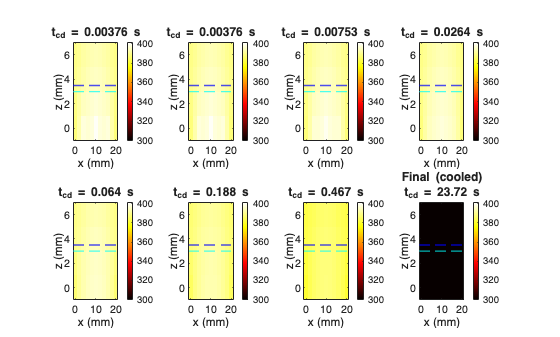


figure(figCool);
subplot(2,4,num_snaps);
imagesc(x*1e3, z*1e3, T_cd); set(gca,'YDir','normal');
set(gca, 'CLim', [T_inf, T_jmax]);
colormap('hot'); colorbar;
title(sprintf('Final (cooled)\nt_{cd} = %.2f s', time_cd));
xlabel('x (mm)'); ylabel('z (mm)');
hold on;
yline(t_die*1e3,         'c--','LineWidth',1);
yline((t_die+t_tim)*1e3, 'b--','LineWidth',1);
hold off;


set(hImgCd, 'CData', T_cd);
title(axC, sprintf('Final (cooled) t = %.3f s', time_cd));
drawnow('expose'); writeVideo(vw_cd, getframe(figAnimCd));
close(vw_cd); close(figAnimCd);
fprintf('Saved cooldown animation: %s\n', videoName_cd);

Saved cooldown animation: cpu_cooldown_explicit.mp4


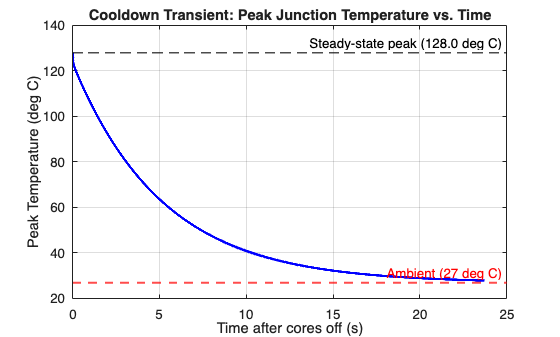


%% =========================================================================
%  TEMPERATURE HISTORY PLOT
% =========================================================================
figure('Name','Peak Junction Temperature - Cooldown Phase','Color','w');
plot(T_time_history, T_peak_history - 273.15, 'b-', 'LineWidth', 2);
xlabel('Time after cores off (s)'); ylabel('Peak Temperature (deg C)');
title('Cooldown Transient: Peak Junction Temperature vs. Time');
grid on;
yline(T_inf - 273.15, 'r--', 'Ambient (27 deg C)', 'LineWidth', 1.5, ...
      'LabelHorizontalAlignment','right');
yline(T_jmax - 273.15, 'k--', sprintf('Steady-state peak (%.1f deg C)', T_jmax-273.15), ...
      'LineWidth', 1.2, 'LabelHorizontalAlignment','right');


fprintf('\nCooldown complete. Total cooldown time: %.2f s\n', time_cd);


Cooldown complete. Total cooldown time: 23.72 s
